Create a rigid body tree to build the robot.

close all
robot = rigidBodyTree;

Create the first rigid body & add it to the robot

body = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt1.HomePosition = pi/4;

% Move to appropriate position in space
tform = trvec2tform([0.25, 0.25, 0])

tform =     1.0000         0         0    0.2500
         0    1.0000         0    0.2500
         0         0    1.0000         0
         0         0         0    1.0000


setFixedTransform(jnt1,tform)

% Add the rigid body to the robot
body.Joint = jnt1

body =   rigidBody with properties:

            Name: 'body1'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


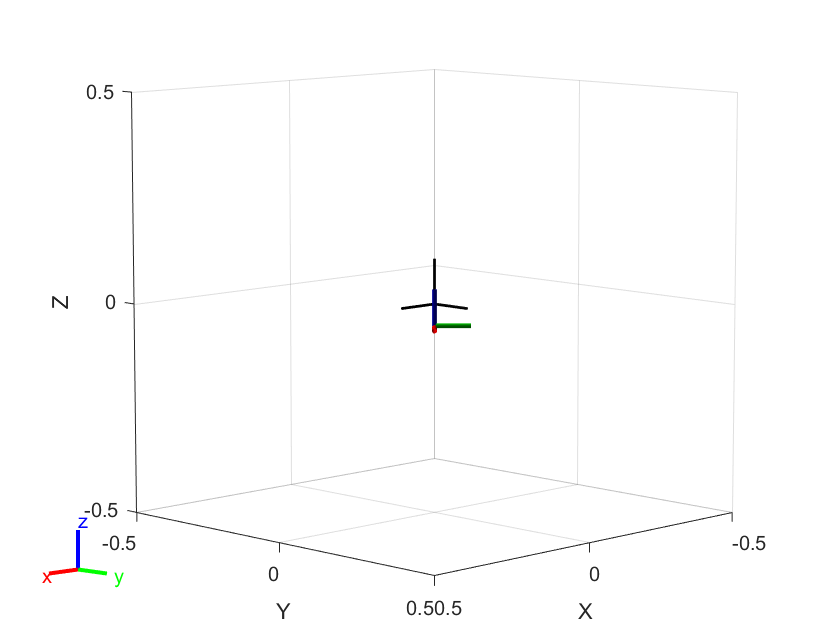

ans =   Axes (Primary) with properties:

             XLim: [-0.5000 0.5000]
             YLim: [-0.5000 0.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


addBody(robot, body, 'base')

figure();
robot.show

Define other joints:

Joint 2:  Revolute joint, at default position of 30 degrees at a distance of 1 unit in the X from joint 1

Joint 3: Revolute joint, at a default position of 0 degrees at a distance of 0.6 units in X and -0.1 units in Y from joint 2 with a frame rotation of -90 degrees about Z

Joint 4: Revolute joint, at default position of 45 degrees at a distance of 1 unit in the X direction from joint 3

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute')

jnt2 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt2'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3', 'revolute')

jnt3 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt3'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4', 'revolute');


Define the homepositions

jnt2.HomePosition = pi/6;
jnt4.HomePosition = pi/4;

Define the transformations

%Joint 2
tform2 = trvec2tform([1, 0 0])

tform2 =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


%Joint 3: translation + rotation
ttrans3 = trvec2tform([0.6, -0.1, 0])

ttrans3 =     1.0000         0         0    0.6000
         0    1.0000         0   -0.1000
         0         0    1.0000         0
         0         0         0    1.0000


trot3 = axang2tform([0, 0, 1, -pi/2])

trot3 =     0.0000    1.0000         0         0
   -1.0000    0.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


tform3 = ttrans3 * trot3

tform3 =     0.0000    1.0000         0    0.6000
   -1.0000    0.0000         0   -0.1000
         0         0    1.0000         0
         0         0         0    1.0000


%Joint 4
tform4 = trvec2tform([1, 0 , 0]);

Apply the trasnformations:

setFixedTransform(jnt2, tform2)
setFixedTransform(jnt3, tform3)
setFixedTransform(jnt4, tform4)

Attach the joints to the corresponding bodies

body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

Attach the bodies to the robot

addBody(robot, body2, 'body1')
addBody(robot, body3, 'body2')
addBody(robot, body4, 'body3')

robot

robot =   rigidBodyTree with properties:

     NumBodies: 4
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'body1'  'body2'  'body3'  'body4'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


figure()
robot.show

ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


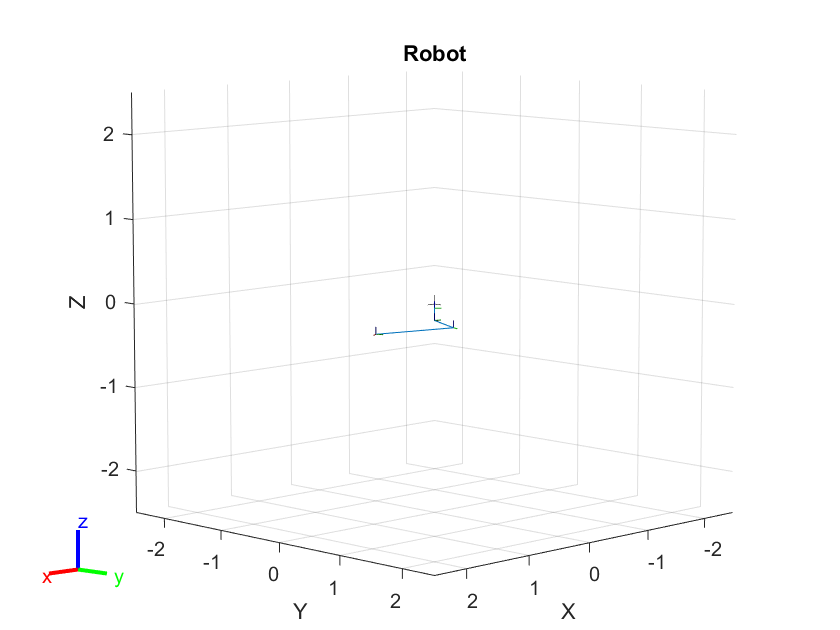

title("Robot")

Results:

getTransform(robot,homeConfiguration(robot), 'body4')

ans =     0.8660   -0.5000         0    2.1749
    0.5000    0.8660         0    1.2520
         0         0    1.0000         0
         0         0         0    1.0000
